# Variables

### 1: How to assign?

You can name the variable whatever you want, as long as it follows some basic conventions

- It cannot start with a number

- It cannot have spaces

- Some characters are off limits(Ex: %, !, @, #, $, *, ^)

x = 1

### 2: Different Data Types

The '%' symbol indicates a comment. It is not executed when you run your code.

disp('-----------')

x = 1

x = 1 % Double

y = [1, 2, 3, 4] % Array (horzontile)
w = [1;2;3;4] % Array (vertical)

-----------


z = [1,2,3,4;5,6,7,8] % Array (Matrix)

x = 1


str = "Hello World" % String

y =      1     2     3     4


ch = 'Hello World' % Character Array

w =      1
     2
     3
     4


z =      1     2     3     4
     5     6     7     8


logic = true % logical type


str = "Hello World"

TBL = array2table(z) % Table

ch = 'Hello World'

# Operations

The math operations are the same as what you remember from your algebra class.

Notice how for multiplication and division, you need to add a dot before the symbol. This is because the absance of a dot implies a matrix operation (matrix operations are a story for another time).

disp('---------------')

logic = logical
   1


% Defining Variables:
x = 3

TBL = 2×4 table
    z1    z2    z3    z4
    __    __    __    __

    1     2     3     4 
    5     6     7     8 


y = 2

% Operations:
z1 = x + y % Addition
z2 = x - y

---------------



z3 = x .* y % Multiplication (Notice the '.')

x = 3

z4 = x ./ y

y = 2


z5 = x .^ y % Exponential

# Functions

### 1: How Functions Work

Functions take inputs and return outputs. These outputs then assigned to whatever variable you choose.

Take the function ones(): It takes a dimension in and returns an array

disp('--------------')

z1 = 5

x = ones(3) % Notice how it is 3 by 3

z2 = 1


% Functions can have more than one input.

z3 = 6

% They may work differently depending on the number

z4 = 1.5000

% of inputs
y = ones(3,2) 

z5 = 9

z = ones(2,3)

### 2: Common Functions You Should Know

#### => disp():

We've been using this function the whole time to separate sections!

disp('------------')

--------------


The display function will display any datatype you insert into the function.

x = 1; % Use a ';' to surpress outputs!

x =      1     1     1
     1     1     1
     1     1     1


disp(x)

If you want to write a more complex message, we reccomend that you change everything into a character array and concatinate it together before you display it.

(See the following section on how to transform data types)

msg1 = 'Hello '; 

y =      1     1
     1     1
     1     1


msg2 = 'World';

z =      1     1     1
     1     1     1


disp([msg1 msg2])
% ^ putting two char arrays next to each other in
% brackets will concatinate them!

#### => string(), double(), and char()

These will transform whatever data type you insert into them into a different data type

disp('-------------')

------------


a = 1
b = string(1)
c = double(b)

     1



The **char()** function is a little bit strange. You can only change strings into chars and chars into strings.

disp('-------------')
x = "Hello"
y = char(x) % works as intended

Hello World



x = 5
z = char(x) % does not work as you may have wanted

#### **=> clear()**

A very simple but useful function. It can be used to remove a variable from the workspace. After you run this function, MATLAB will no longer 'remember' the variables you have cleared.

clear() % Clears ALL current variables

-------------


a = 1

% How to clear only one variable:

b = "1"

x = 1

c = 1

y = x + 1
clear("x") % The name of the variable is a string!

-------------


#### **=> plot()**

Very powerful in lab. Can be used to plot two arrays of the same dimension

x = [1 2 3 4 5 6]

x = "Hello"

y = x.^2

y = 'Hello'


plot(x,y)

x = 5

You can also change how the data is displayed with the third input to the function. The codes that control the plot can be found online here:

Appearence: [https://www.mathworks.com/help/matlab/creating_plots/specify-line-and-marker-appearance-in-plots.html](https://www.mathworks.com/help/matlab/creating_plots/specify-line-and-marker-appearance-in-plots.html)

Colors: [https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html](https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html)

% Example:

z = '□'

plot(x,y,'ro-')

% You can label the graph with the commands:
xlabel("x")
ylabel("y")
title("title")

#### **=> readmatrix() or readtable()**

When doing research you will often need to import spreadsheets or CSV files. Use the readmatrix function to help you with this.

Documentation: [https://www.mathworks.com/help/matlab/ref/readmatrix.html](https://www.mathworks.com/help/matlab/ref/readmatrix.html)

filename = 'S&P500Tickers.csv'

x = 1

y = 2

% readmatrix will bring the data to an array type
% This will not always work
X = readmatrix(filename)

% readtable will bring the data to a table type

x =      1     2     3     4     5     6


% this will likely be what you want!

y =      1     4     9    16    25    36


Y = readtable(filename)

Notice that if you run the previous code you will get a warning which tells you to set 'VariableNamingRule' to 'preserve'. This is because many functions in MATLAB will have configurable options that you can modify. These options will take the form of charactor array inputs as shown below.

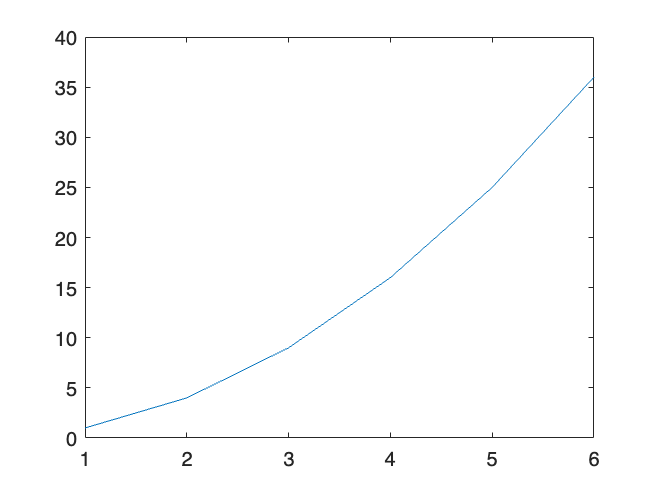

% Preserve the variable names (as the warning suggested)

Z = readtable(filename,'VariableNamingRule','preserve')

# Conditionals

These statements can be used to run code based on the value of a logical array. Make sure to use the correct syntax!

#### Example 1: Basic Conditional Structure

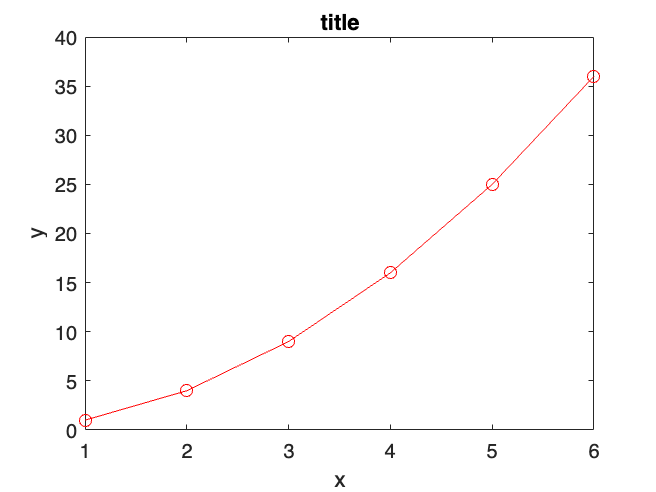

x = true 
if x % Checks if the statement is true

    disp("Hello") % Body of conditional code

end % You cannot forget the "end" statement

#### Example 2: Using Logical Operators

The below statement is false if x = 1 and y = 2, so "Hello" will not be displayed!

x = 1

filename = 'S&P500Tickers.csv'

y = 2

disp("Runs Before Conditional")
if y <= x % This is false

X =          NaN         NaN         NaN         NaN         NaN         NaN     1090872        1999
         NaN         NaN         NaN         NaN         NaN         NaN        6201        1934
         NaN         NaN         NaN         NaN         NaN         NaN     1158449        1932
         NaN         NaN         NaN         NaN         NaN         NaN      320193        1977
         NaN         NaN         NaN         NaN         NaN         NaN     1551152         NaN
         NaN         NaN         NaN         NaN         NaN         NaN     1140859        1985
         NaN         NaN         NaN         NaN         NaN         NaN      815094        1981
         NaN         NaN         NaN         NaN         NaN         NaN        1800        1888
         NaN         NaN         NaN         NaN         NaN         NaN     1467373        1989
         NaN         NaN         NaN         NaN         NaN         NaN      796343        1982


    disp("Hello")
end
disp("Runs After Conditional")

#### Example 3: Evaluate multiple logical statements at once

You don't need to evaluate the logical statement in the conditional itself. You can assign it to a logical variable type beforehand.

You are also able to use other logical statemetns like "&" for and, "|" for or, and ~ for not.

disp("------------")

Y = 505×8 table
     Symbol               Security                       GICSSector                           GICSSub_Industry                        HeadquartersLocation         DateFirstAdded       CIK        Founded
    ________    _____________________________    __________________________    ______________________________________________    ______________________________    ______________    __________    _______

    {'A'   }    {'Agilent Technologies Inc' }    {'Health Care'           }    {'Health Care Equipment'                     }    {'Santa Clara, California'   }     05-Jun-2000      1.0909e+06     1999  
    {'AAL' }    {'American Airlines Group'  }    {'Industrials'           }    {'Airlines'            

x = 1
y = 2
z = 3

Z = 505×8 table
     Symbol               Security                      GICS Sector                          GICS Sub-Industry                       Headquarters Location         Date first added       CIK        Founded
    ________    _____________________________    __________________________    ______________________________________________    ______________________________    ________________    __________    _______

    {'A'   }    {'Agilent Technologies Inc' }    {'Health Care'           }    {'Health Care Equipment'                     }    {'Santa Clara, California'   }      05-Jun-2000       1.0909e+06     1999  
    {'AAL' }    {'American Airlines Group'  }    {'Industrials'           }    {'Airlines'      


condition = x ~= y | y < z

if condition
    disp("Condition is Success!")

x = logical
   1


end

Hello


#### **Example 4: elseif and else**

Sometimes you want your if statement to run another block of code if the first if statement is not satisfied.

disp("--------")

x = 1

x = 1

y = 2

y = 2
z = 3

Runs Before Conditional



disp("If Statement #1")
if x > y
    disp("If Statement is True")

Runs After Conditional


elseif y > x
    disp("elseif statemet is true")
else
    disp("Else condition")
end

------------


x = 1

disp("If Statement #2")

y = 2

if x > y

z = 3

    disp("If Statement is True")
elseif z < x

condition = logical
   1


    disp("elseif statemet is true")
else
    disp("Else condition")
end

Condition is Success!


# Loops

Loop statements are the backbone of coding. They allow you to execute the same code over and over again with different parameters

### For Loops:

For loops will iterate through an array over and over again. On each iteration it will take the value in the array

for i = ["Never","Gonna","Give","You","Up"]

--------


    disp(i)

x = 1

end

y = 2

z = 3

for i = [1,2,3,4,5]
    x = i * 3;

If Statement #1


    disp(x)
end

elseif statemet is true


### While Loops:

While loops will continue looping until the condition is false. You can thing of it like a looping if statement.

x = 0

If Statement #2


y = 6

while x < y
    x = x + 1;
    disp(x)
end

Else condition


### Loop Example: Solving Differential Equations:

You can use for loops to solve differential equations by brute force. Here we used it to solve x = -x''

The following code was generated using Chat-GPT 3.5:

% Define the time span and time step
tspan = [0, 10];  % Time span from 0 to 10
dt = 0.01;       % Time step


Never
Gonna
Give
You
Up


% Create an array to store the time values
t = tspan(1):dt:tspan(2);

% Initialize arrays to store the values of x and x'
x = zeros(size(t));

     3

     6

     9

    12

    15



x_prime = zeros(size(t));

% Initial conditions
x(1) = 0;      % Initial position

x = 0

x_prime(1) = 1;  % Initial velocity

y = 6


% Numerical integration using a for loop
for i = 1:length(t)-1
    x_double_prime = -1 * x(i);  % Second derivative (x'')
    

     1

     2

     3

     4

     5

     6



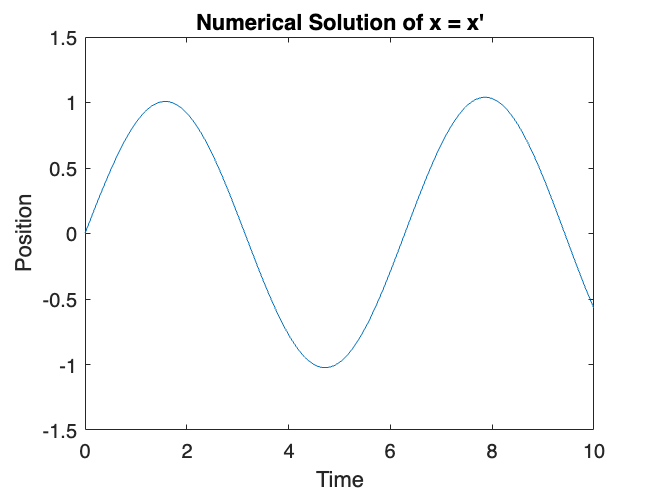

    % Update x' (velocity) and x (position) using Forward Euler method
    x_prime(i+1) = x_prime(i) + x_double_prime * dt;
    x(i+1) = x(i) + x_prime(i) * dt;
end

% Plot the solution
plot(t, x);
xlabel('Time');
ylabel('Position');
title('Numerical Solution of x = x''');

# Some Parting Tips:

- **Don't Sleep On Apps: **You don't need to worry about hand coding absolutely everything. There are so many pre-built apps in the app tab that may do exactly what you want!

- **Documentation: **MATLAB documentation is extensive and thorough. If you don't know how to accomplish a task, odds are there is already a function that can do it. Look it up!

- **Vectorize Your Code:** This is a more advanced concept, but MATLAB is significantly faster at working with matrices and vectors than for loops. For example, if you want to take the mean, use the function "mean()" on an array. Do NOT use a for loop to add the numbers in the array and divide by the length of the array. [https://www.mathworks.com/help/matlab/matlab_prog/vectorization.html](https://www.mathworks.com/help/matlab/matlab_prog/vectorization.html)